clc;
clear all;

%   DH  = [  a_n  alpha_n  d_n  theta_n]
DHparameter=[0 0 0.04 0;
             0.12 pi/2 0 13*pi/30;
             0.194 0 0 -23*pi/30;
             0 -pi/2 0.176 0;
             0 pi/2 0 pi/2;
             0 pi/2 0 0]

DHparameter =          0         0    0.0400         0
    0.1200    1.5708         0    1.3614
    0.1940         0         0   -2.4086
         0   -1.5708    0.1760         0
         0    1.5708         0    1.5708
         0    1.5708         0         0


%Defining a Robot Rigid Body Tree 
dental = robotics.RigidBodyTree;

%Setting the Gravity matrix w.r.t to the base frame of robot.
dental.Gravity = [0 0 -9.81];

%Creating links and joints
body1 = robotics.RigidBody('Body1');
joint1 = robotics.Joint('Joint1','revolute');
body1.Mass = 10;
body1.CenterOfMass = [0 0 0];
joint1.PositionLimits = [0 2*pi];
body2 = robotics.RigidBody('Body2');
joint2 = robotics.Joint('Joint2','revolute');
body2.Mass = 10;
body2.CenterOfMass = [0 0 0];
joint2.PositionLimits = [-2*pi/3 0];

body3 = robotics.RigidBody('Body3');
joint3 = robotics.Joint('Joint3','revolute');
body3.Mass = 10;
body3.CenterOfMass = [0 0 0];
joint3.PositionLimits = [-pi/3 pi/3];

body4 = robotics.RigidBody('Body4');
joint4 = robotics.Joint('Joint4','revolute');
body4.Mass = 10;
joint4.PositionLimits = [0 2*pi];

body5 = robotics.RigidBody('Body5');
joint5 = robotics.Joint('Joint5','revolute');
body5.Mass = 10;
joint5.PositionLimits = [-pi/4 pi/4];

body6 = robotics.RigidBody('Body6');
joint6 = robotics.Joint('Joint6','revolute');
body6.Mass = 10;
joint6.PositionLimits = [-pi/4 pi/4];

%Settings the transformations to each joint with DH parameter.
%Assigning the joint of each link with the object 
setFixedTransform(joint1,DHparameter(1,:),"dh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"dh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"dh");
body3.Joint = joint3;
setFixedTransform(joint4,DHparameter(4,:),"dh");
body4.Joint = joint4;
setFixedTransform(joint5,DHparameter(5,:),"dh");
body5.Joint = joint5;
setFixedTransform(joint6,DHparameter(6,:),"dh");
body6.Joint = joint6;

addBody(dental,body1,'base');
addBody(dental,body2,'Body1');
addBody(dental,body3,'Body2');
addBody(dental,body4,'Body3');
addBody(dental,body5,'Body4');
addBody(dental,body6,'Body5');

dental.DataFormat= "Column"

dental =   rigidBodyTree with properties:

     NumBodies: 6
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'Body1'  'Body2'  'Body3'  'Body4'  'Body5'  'Body6'}
      BaseName: 'base'
       Gravity: [0 0 -9.8100]
    DataFormat: 'column'


showdetails(dental)

--------------------
Robot: (6 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   
--------------------


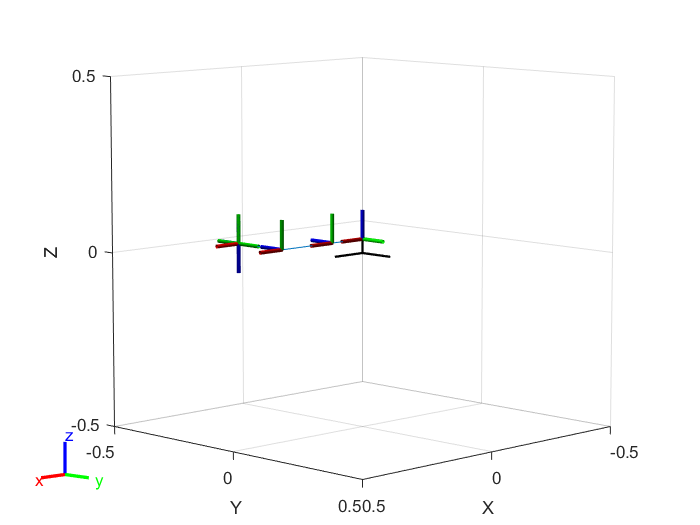


show(dental);

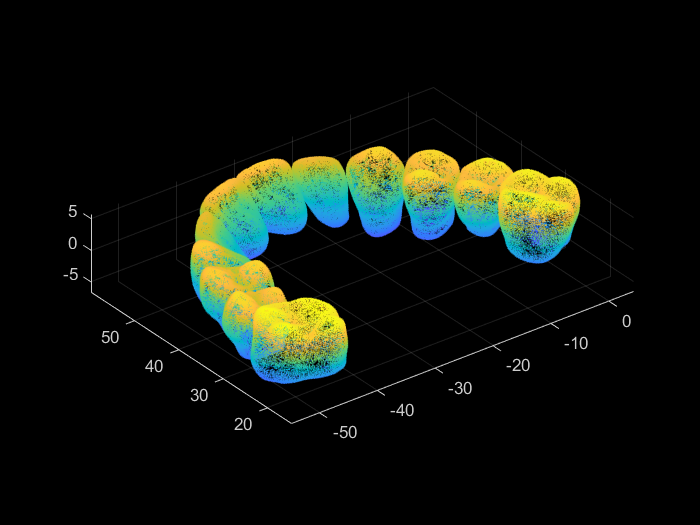

% Read and plot complete denture
stlData = stlread('stl/1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);
figure
pcshow(ptCloud)

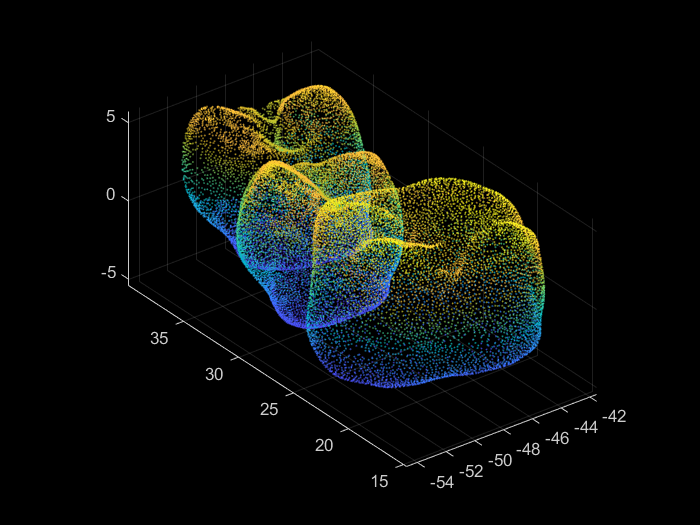



% Select and plot three teeth individually
roi = [-60 -40 10 40 -6 6]; % region of interest
indices = findPointsInROI(ptCloud,roi);
ptCloudB = select(ptCloud, indices);
pcshow(ptCloudB.Location);

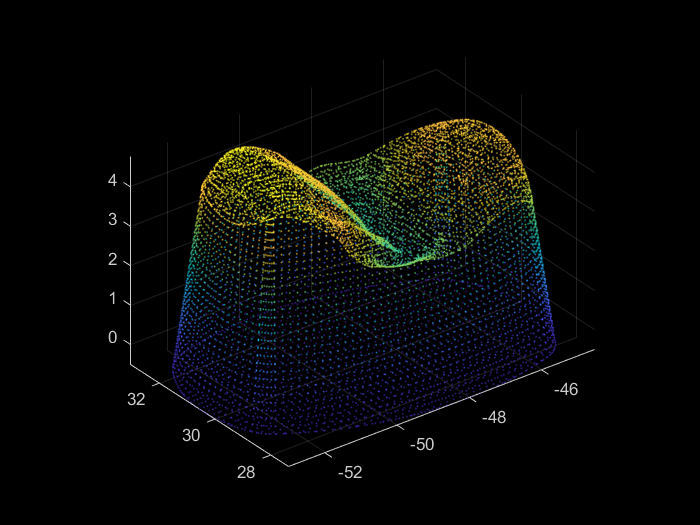

% Import and plot final model individually
stlData_fin = stlread("stl/1tooth_mesh2.STL");

points_fin= stlData_fin.Points;
ptCloud_fin = pointCloud(points_fin);
pcshow(ptCloud_fin);

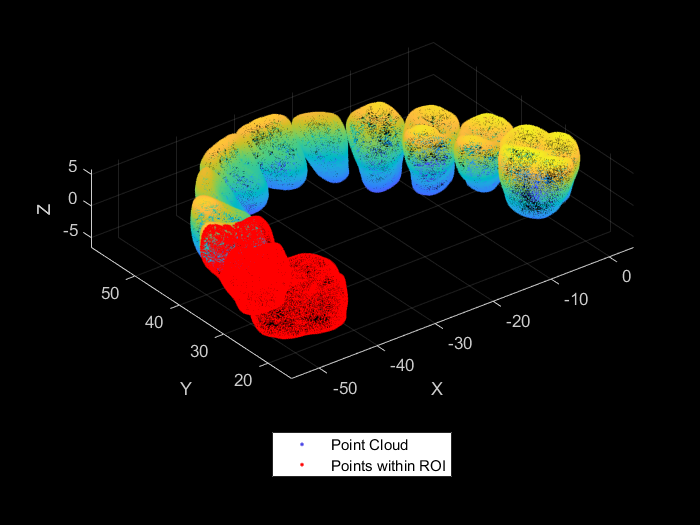

% Three teeth in the denture
figure
pcshow(ptCloud);
hold on;
pcshow(ptCloudB.Location,'r');
legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
xlabel('X'); ylabel('Y'); zlabel('Z');
hold off;

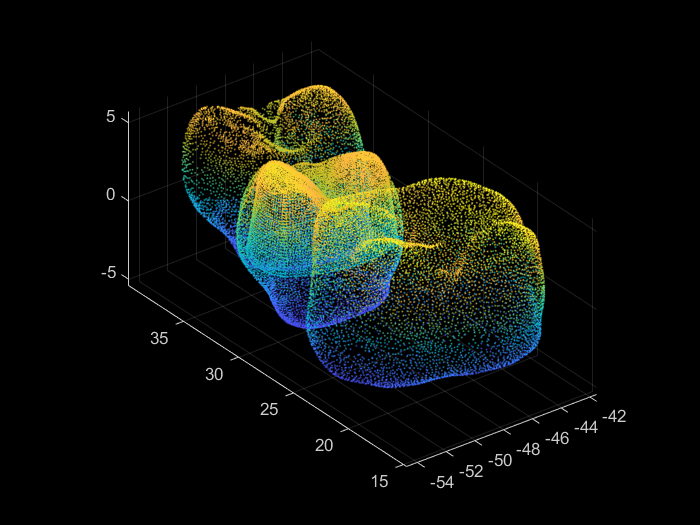

% Final tooth inside the considered tooth
figure
pcshow(ptCloudB.Location);
hold on;
pcshow(ptCloud_fin);
hold off;

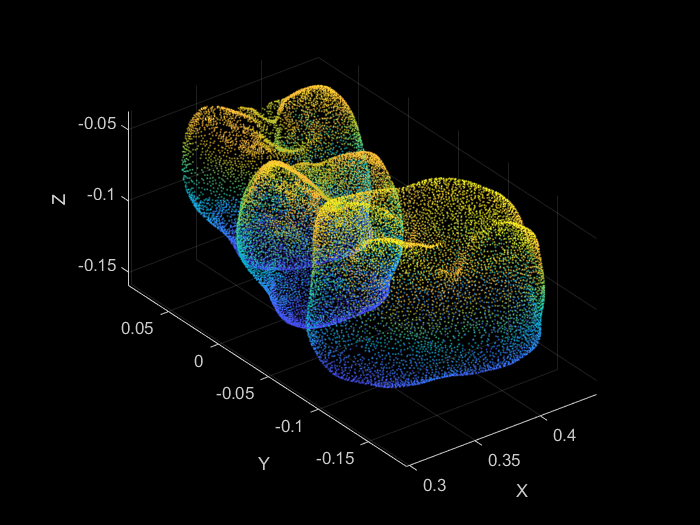

%Transformation (shrink and move)
Sx = 0.011;
Sy = 0.011;
Sz = 0.011;


tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud_3t = pctransform(ptCloudB,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
zCoord = -0.1;
trans = [0.9 -0.35 zCoord];
tform = rigid3d(rot,trans);
ptCloud_3t = pctransform(ptCloud_3t,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);

figure
pcshow(ptCloud_3t)
xlabel('X'); ylabel('Y'); zlabel('Z')

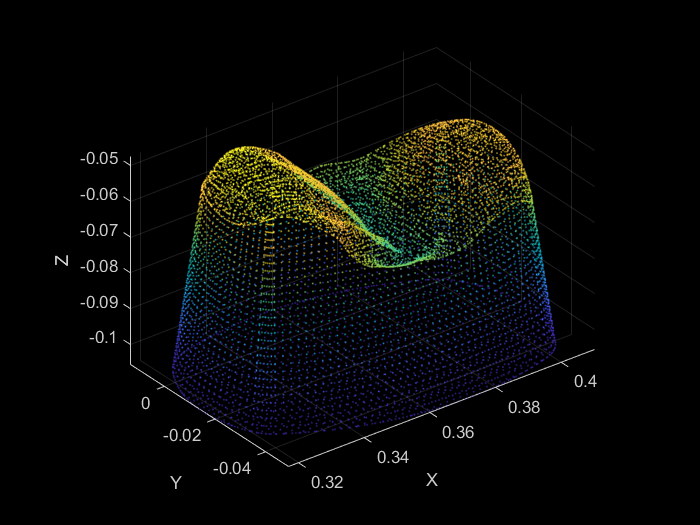

pcshow(ptCloud_fin)
xlabel('X'); ylabel('Y'); zlabel('Z')

MSH = collisionMesh(ptCloud_fin.Location)

MSH =   collisionMesh with properties:

    Vertices: [10770×3 double]
        Pose: [4×4 double]


worldCollisionArray = {MSH}

worldCollisionArray = 1×1 cell array
    {1×1 collisionMesh}


figure;
show(dental)

ans =   Axes (Primary) with properties:

             XLim: [-0.5000 0.5000]
             YLim: [-0.5000 0.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


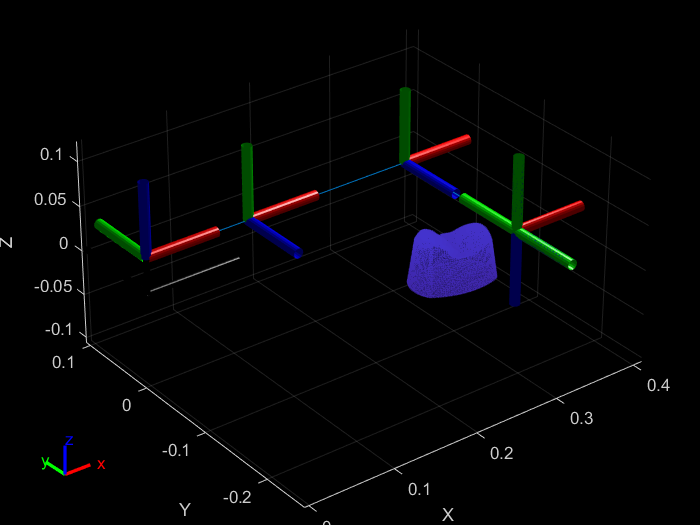

hold on;
pcshow(ptCloud_fin)

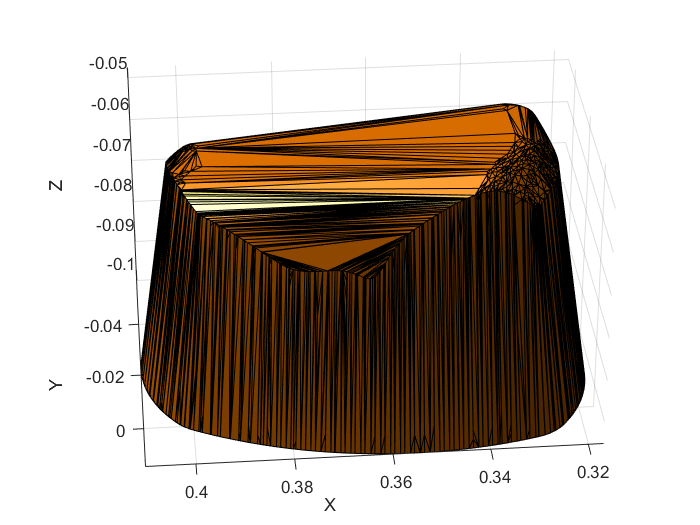

ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);

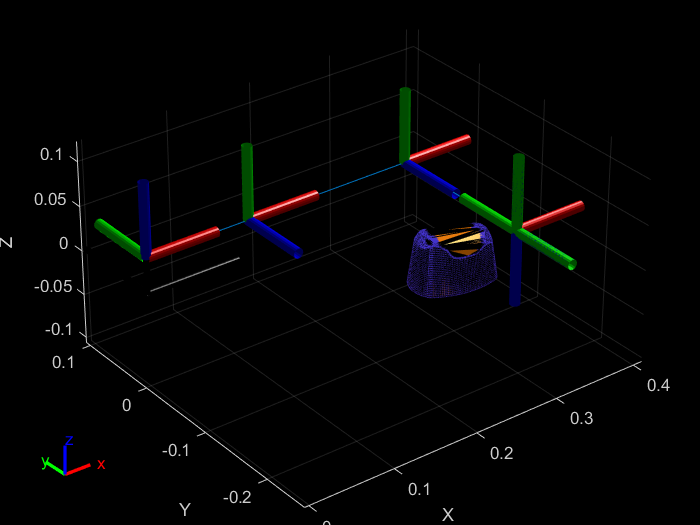

show(dental,homeConfiguration(dental),"Parent",ax);
hold on;
pcshow(ptCloud_fin)

figure
allPoints = {};
r = 0.005

r = 0.0050

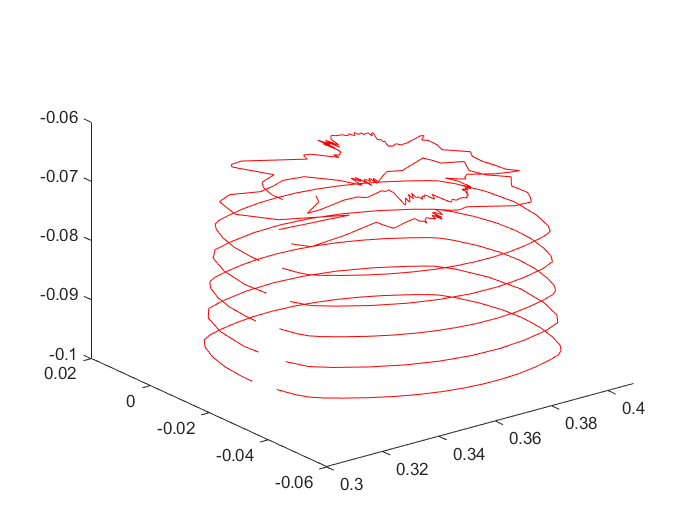

for i=1:7
    L = zCoord + (i-1)*r;
    H = zCoord + r + (i-1)*r;
    [a,b] = getContour(ptCloud_fin,L,H);
    P = getOrderedPoints(a,b);
    [smoothX,smoothY] = smoothCurve(P,35,2);
    
    points = downsample([smoothX',smoothY'],10);
   
    polyin = polyshape({points(:,1)},{points(:,2)});
    polyout = polybuffer(polyin,0.005);
    
    zin = (L+H)/2 * ones(length(polyin.Vertices),1);
    allPoints{i} = [points,zin];
%     zout = (L+H)/2 * ones(length(polyout.Vertices));
    
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),zin,"Color",[1 0 0]); hold on;
%     plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),zout,"Color",[0 1 0]);
end

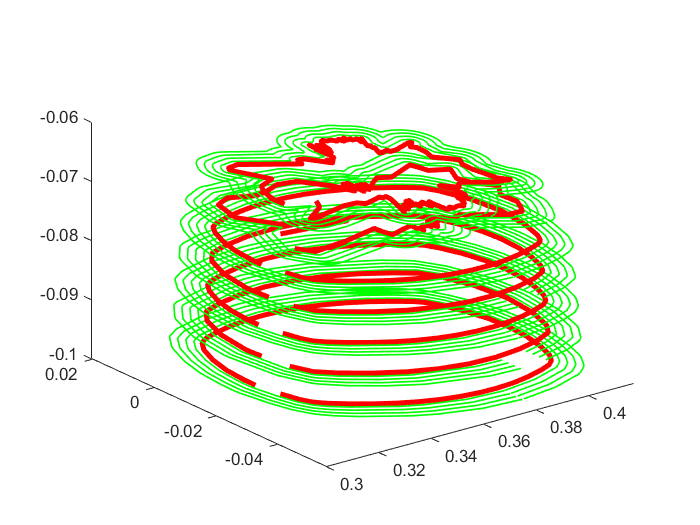

figure
for i=1:length(allPoints)
    polyin = polyshape({allPoints{1,i}(:,1)},{allPoints{1,i}(:,2)});
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),allPoints{1,i}(:,3),...
            "Color",[1 0 0],"LineWidth",3);
    hold on;
    for j=1:4
        polyout = polybuffer(polyin,0.002*j);
        polyout.Vertices = downsample(polyout.Vertices,5);
        z = allPoints{1,i}(1,3)*ones(length(polyout.Vertices),1);
        allPoints{j+1,i} = [polyout.Vertices, z];
        plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),z,...
                "Color",[0 1 0],"LineWidth",1);
    end
end

allPoints

allPoints = 5×7 cell array
    {43×3 double}    {29×3 double}    {43×3 double}    {31×3 double}    {41×3 double}    { 81×3 double}    {164×3 double}
    {45×3 double}    {42×3 double}    {45×3 double}    {42×3 double}    {45×3 double}    {189×3 double}    {313×3 double}
    {45×3 double}    {42×3 double}    {45×3 double}    {42×3 double}    {45×3 double}    {143×3 double}    {228×3 double}
    {45×3 double}    {42×3 double}    {45×3 double}    {42×3 double}    {45×3 double}    {126×3 double}    {183×3 double}
    {45×3 double}    {42×3 double}    {45×3 double}    {42×3 double}    {45×3 double}    {115×3 double}    {153×3 double}


%Row: Top to bottom - Inside to Outside
%Column : Left to right - Bottom to top

curve1 = allPoints{5,1};
pt = []


pt =

     []



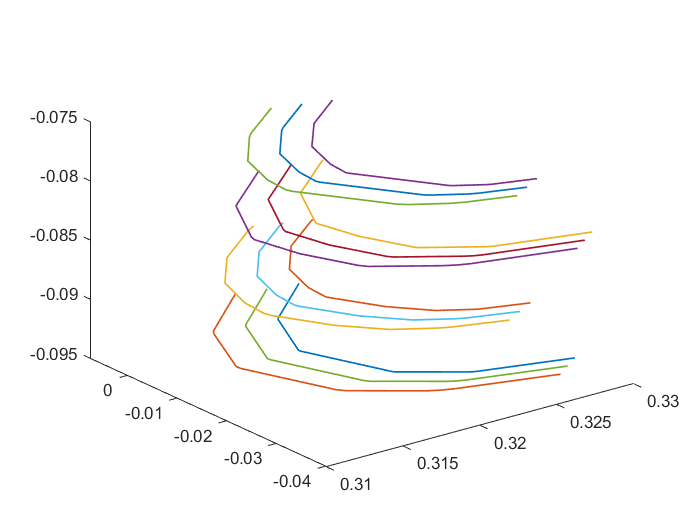

a = 10

a = 11

a = 10

a = 11

a = 10

a = 11

a = 10

a = 11

a = 10

a = 11

a = 10

a = 11

figure
for i=2:4
    for j=2:5
        [q1,q2,q3,q4] = getQuarters(allPoints{i,j},1);
        pt = [pt; q1];
    end
end

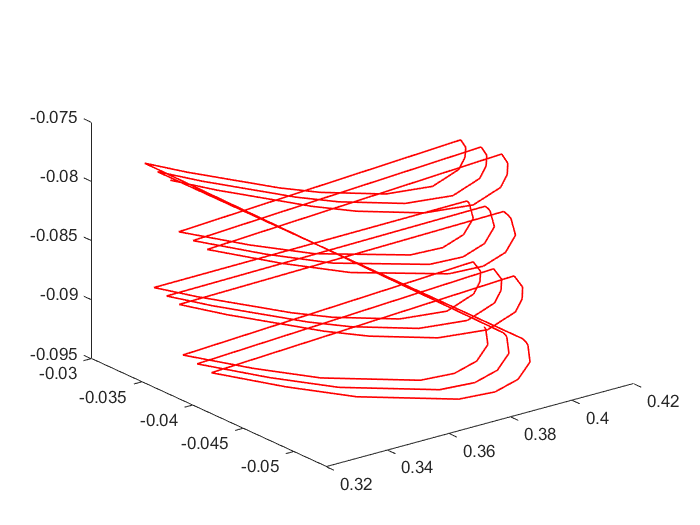

figure;
pt;
q=[pt];
plot3(q(:,1),q(:,2),q(:,3),'r',"LineWidth",1);

% curve2 = allPoints{5,1};
% 
% figure
% for i=1:7
%     for j=1:5
%         [q12,q22,q32,q42] = getQuarters(allPoints{j,i},1);
%     end
% end
% q12


% figure
% [q1,q2,q3,q4] = getQuarters(allPoints{5,1},1);

q1

q1 =     0.4031   -0.0454   -0.0775
    0.4003   -0.0468   -0.0775
    0.3951   -0.0483   -0.0775
    0.3880   -0.0498   -0.0775
    0.3746   -0.0512   -0.0775
    0.3744   -0.0512   -0.0775
    0.3610   -0.0505   -0.0775
    0.3479   -0.0478   -0.0775
    0.3410   -0.0455   -0.0775
    0.3287   -0.0398   -0.0775


% q2
q=[pt]

q =     0.3273    0.0076   -0.0975
    0.3240    0.0042   -0.0975
    0.3209   -0.0012   -0.0975
    0.3188   -0.0075   -0.0975
    0.3179   -0.0140   -0.0975
    0.3179   -0.0177   -0.0975
    0.3193   -0.0245   -0.0975
    0.3210   -0.0294   -0.0975
    0.3228   -0.0321   -0.0975
    0.3255   -0.0343   -0.0975


count = length(q)

count = 203

q0 = homeConfiguration(dental);
ndof = length(q0)

ndof = 6

% Container to store the Inverse Kinematic Solver solution
qs = zeros(count, ndof);
ik = inverseKinematics('RigidBodyTree', dental);
weights = [0, 0, 0, 1, 1, 1];
endEffector = 'Body6';
qInitial = q0; % Use home configuration as the initial guess
for i = 1:count
    % Solve for the configuration satisfying the desired end effector
    % position
    point = q(i,:);
    qSol = ik(endEffector,trvec2tform(point),weights,qInitial);
    % Store the configuration
    qs(i,:) = qSol;
    % Start from prior solution
    qInitial = qSol;
end

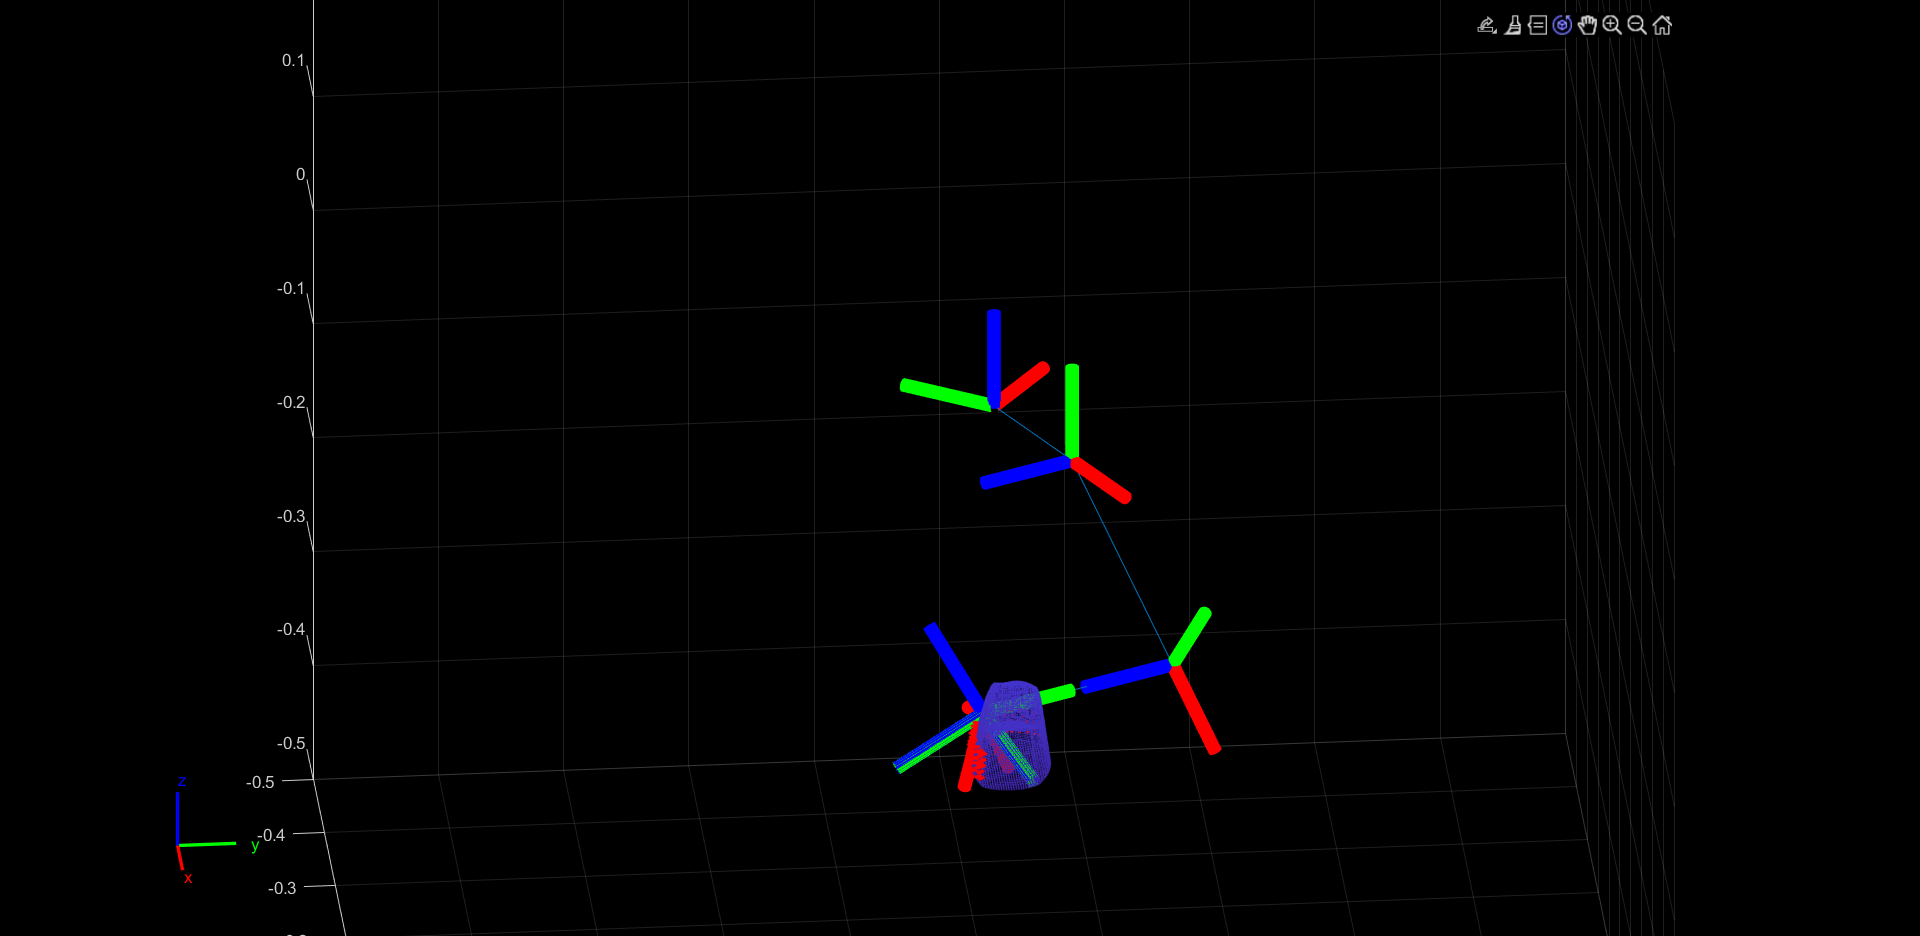

close all
figure;
hold on
grid on
for i = 1:count
    show(dental,qs(i,:)','PreservePlot',false);
    plot3(q(i,1),q(i,2),q(i,3),'r.',"LineWidth",1);
    pcshow(ptCloud_fin)
    axis([-0.5,0.5,-0.5,0.5,-0.5,0.5])
    pause(0.1)
    view([85 25])
end
hold off;

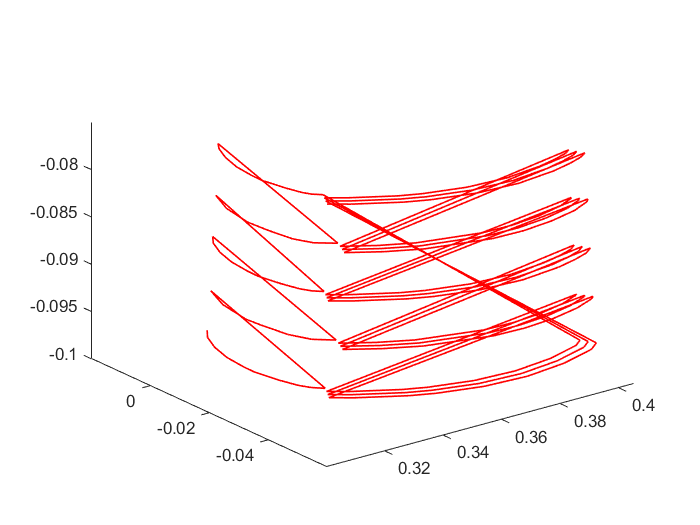


plot3(q(:,1),q(:,2),q(:,3),'r',"LineWidth",1);

% rng(0);
% % startPose = trvec2tform([-0.5,0.5,0.4])*axang2tform([1 0 0 pi]);
% ik = inverseKinematics("RigidBodyTree",dental);
% weights = ones(1,6);
% startConfig = ik("EndEffector_Link",startPose,weights,robot.homeConfiguration);
% endConfig = ik("EndEffector_Link",endPose,weights,robot.homeConfiguration);
% 
% % Show initial and final positions
% show(robot,startConfig);
% show(robot,endConfig);

function [ax, figHandle] = exampleHelperVisualizeCollisionEnvironment(collisionObjectArray)
%exampleHelperVisualizeCollisionEnvironment Visualize a set of collision objects
%   given a cell array of collision objects, create a figure that plots
%   these and with hold on. Return the handle to the figure's axis.
figHandle = figure;

% Show the first object
show(collisionObjectArray{1});

% Get axis properties and set hold
ax = gca;
hold all;

% Show remaining objects
for i = 2:numel(collisionObjectArray)
    show(collisionObjectArray{i}, "Parent", ax);
end

% Set axis properties
axis equal;

end
function plotWorkspace(DH,q)
    % drawworkspace
    %{
    This function plots a workspace for a planar n-DOF revolute or prismatic
    given DH parameters and the constraints of all variables.
    
    This function uses Robotics Toolbox by Peter Corke which can be
    downloaded from :
    https://petercorke.com/wordpress/toolboxes/robotics-toolbox
    ----------------------------------------------
    Inputs
    DH    DH parameters each row is a link
    q     a cell input contains constraints for all variables
            ordered from first link to last link.
    ---------------------------------------------------------------------
    Example
    a1 = 0.5; 
    a2 = 0.3; 
    a3 = 0.2;
    DH(1) = Link([0 0 a1 0]);
    DH(2) = Link([0 0 a2 0]);
    DH(3) = Link([0 0 a3 0]);
    th1 = (-pi/6:0.05:pi/6) ;
    th2 = (-2*pi/3:0.05:2*pi/3);
    th3 = (-pi/2:0.05:pi/2) ;
    q = {th1,th2,th3};
    
    All copyrights go to Mohammad Al-Fetyani
    University of Jordan
    %}
    
    % L = Link([Th d a alpha])
    r = SerialLink(DH);
    r.display();
    [~,n] = size(DH);
    
    
    var = sym('q',[n 1]);
    assume(var,'real')
    
    % generate a grid of theta1 and theta2,3,4 values
    [Q{1:numel(q)}] = ndgrid(q{:});
    T = simplify(vpa(r.fkine(sym(var)),3));
    Pos = T.tv;
    x(var(:)) = Pos(1);
    X = matlabFunction(x);
    X = X(Q{:});
    y(var(:)) = Pos(2);
    Y = matlabFunction(y);
    Y = Y(Q{:});
    z(var(:)) = Pos(3);
    Z = matlabFunction(z);
    Z = Z(Q{:});
    plot3(X(:),Y(:),Z(:),'r.')
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
end

### `getContour`

function [a,b] = getContour(ptCloud,L,H)
    k = 1;
    
    for i = 1:length(ptCloud.Location(:,3))
        j = ptCloud.Location(i,3);
        if j < H && j > L
            a(k,1) = ptCloud.Location(i,1);
            b(k,1) = ptCloud.Location(i,2);
            k = k+1;
        end
    end
end

### `getOrderedPoints`

function [P] = getOrderedPoints(a,b)
    P = [a'; b']; % coordinates / points 
    c = mean(P,2); % mean/ central point 
    d = P-c ; % vectors connecting the central point and the given points 
    th = atan2(d(2,:),d(1,:)); % angle above x axis
    [th, idx] = sort(th);   % sorting the angles 
    P = P(:,idx); % sorting the given points
    P = [P P(:,1)]; % add the first at the end to close the polygon 
end

### `smoothCurve`

function [smoothX, smoothY] = smoothCurve(P,windowWidth,polynomialOrder)
    smoothX = sgolayfilt(P(1,:), polynomialOrder, windowWidth);
    smoothY = sgolayfilt(P(2,:), polynomialOrder, windowWidth);
end

### `createFit1`

function [fitresult, gof, yData, xData] = createFit1(b1, a1)
    %CREATEFIT1(B1,A1)
    %  Create a fit.
    %
    %  Data for 'untitled fit 1' fit:
    %      X Input : b1
    %      Y Output: a1
    %  Output:
    %      fitresult : a fit object representing the fit.
    %      gof : structure with goodness-of fit info.
    %
    %  See also FIT, CFIT, SFIT.
    
    %  Auto-generated by MATLAB on 14-Nov-2021 06:56:48
    
    
    %% Fit: 'untitled fit 1'.
    [xData, yData] = prepareCurveData( b1, a1 );
    
    % Set up fittype and options.
    ft = fittype( 'smoothingspline' );
    opts = fitoptions( 'Method', 'SmoothingSpline' );
    opts.Normalize = 'on';
    opts.SmoothingParam = 0.997023529294237;
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    % Plot fit with data.
    figure( 'Name', 'untitled fit 1' );
    h = plot( fitresult, xData, yData );
    legend( h, 'a1 vs. b1', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
    % Label axes
    xlabel( 'b1', 'Interpreter', 'none' );
    ylabel( 'a1', 'Interpreter', 'none' );
    grid on
end

### `getQuarters`

function [q1,q2,q3,q4] = getQuarters(curve1,flag)    
    a = floor(length(curve1)/4);
    a
    curve1 = circshift(curve1,floor(a/2));
    curve1 = [curve1; curve1(1,:)];
    q1 = [curve1((1:a),1),curve1((1:a),2),curve1((1:a),3)];
    q2 = [curve1((a:2*a),1),curve1((a:2*a),2),curve1((a:2*a),3)];
    q3 = [curve1((2*a:3*a),1),curve1((2*a:3*a),2),curve1((2*a:3*a),3)];
    q4 = [curve1((3*a:end),1),curve1((3*a:end),2),curve1((3*a:end),3)];
    
    if(flag==1)
%         plot3(q1(:,1),q1(:,2),q1(:,3),'r',"LineWidth",1);hold on;
        plot3(q2(:,1),q2(:,2),q2(:,3),"LineWidth",1);hold on;
%         plot3(q3(:,1),q3(:,2),q3(:,3),"LineWidth",1);hold on;
%         plot3(q4(:,1),q4(:,2),q4(:,3),"LineWidth",1);hold on;
    end
end

A Function that takes starting, ending point & number of points in between and returns the coordinates of those points.

function [xx,yy]=fillline(startp,endp,pts)
        m=(endp(2)-startp(2))/(endp(1)-startp(1)); %gradient 
        if m==Inf %vertical line
            xx(1:pts)=startp(1);
            yy(1:pts)=linspace(startp(2),endp(2),pts);
        elseif m==0 %horizontal line
            xx(1:pts)=linspace(startp(1),endp(1),pts);
            yy(1:pts)=startp(2);
        else %if (endp(1)-startp(1))~=0
            xx=linspace(startp(1),endp(1),pts);
            yy=m*(xx-startp(1))+startp(2);
        end
end
% function [ax, figHandle] = exampleHelperVisualizeCollisionEnvironment(collisionObjectArray)
% %exampleHelperVisualizeCollisionEnvironment Visualize a set of collision objects
% %   given a cell array of collision objects, create a figure that plots
% %   these and with hold on. Return the handle to the figure's axis.
% figHandle = figure;
% 
% % Show the first object
% show(collisionObjectArray{1});
% 
% % Get axis properties and set hold
% ax = gca;
% hold all;
% 
% % Show remaining objects
% for i = 2:numel(collisionObjectArray)
%     show(collisionObjectArray{i}, "Parent", ax);
% end
% 
% % Set axis properties
% axis equal;
% 
% end